姓名：莊璧如  學號：111321534

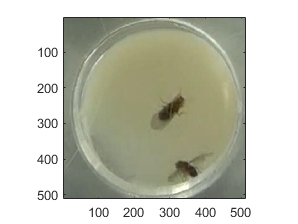

v=VideoReader('flyman512x512.avi');
video = readFrame(v);
i=0;
while hasFrame(v)
    video = readFrame(v);
    image(video), axis square
    drawnow
    i=i+1;
end

k=imread('flymanBG.jpg');
bg = rgb2gray(k)

bg = 512×512 uint8 matrix
   106   106   106   105   105   105   104   104   104   104   104   104   104   104   104   104   103   103   103   104   104   105   105   105   106   106   106   105   105   104   104   104   104   104   104   104   104   104   104   104   103   103   103   103   103   103   103   103   104   104
   106   105   105   105   104   104   104   103   104   104   104   104   104   104   104   104   103   103   103   104   104   105   105   105   106   106   106   105   105   104   104   104   104   104   104   104   104   104   104   104   103   103   103   103   103   103   103   103   104   104
   105   104   104   104   103   103   103   102   103   103   103   103   103   103   103   103   103   103   103   104   104   105   105   105   106   106   106   105   105   104   104   104   104   104   104   104   104   104   104   104   103   103   103   103   103   103   103   103   104   104
   104   104   103   103   103   102   102   102   103   103   103   10

       
video=double(video);
bg=double(bg);
g=video-bg;
g=abs(g);
g=(g+255)/2;
imshow(abs(g),[]);

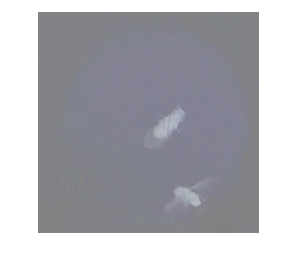

g=uint8(g);
imshow(g);

ex2

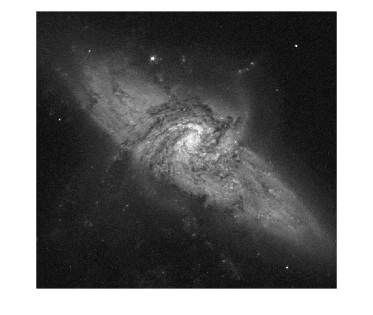

r=imread('Fig3.30(a).jpg');
r=double(r);
i=0;
while (i<16) 
    t=randn(size(r));
    r=t+r;
    i=i+1;
    imshow(r,[]);
end

r=r/16

r =     1.6152    1.5623    1.8868    1.7028    1.4959    1.7268    1.4028    1.2879    1.6534    1.9747    1.8487    1.9172    2.0655    1.6507    1.9208    1.6753    1.7870    1.4509    1.6520    2.2949    1.8555    1.7580    1.6411    2.3145    2.4305    2.4123    2.4176    2.4451    2.4030    1.8450    1.7534    1.5327    1.9555    1.4250    1.9875    1.6516    1.8475    2.3206    1.7031    1.8204    1.7450    2.1594    2.1671    1.5555    1.9439    1.6634    1.7868    1.2548    1.8959    1.7534
    1.8907    1.5316    2.0134    1.6406    1.4438    1.4497    1.5471    1.6430    2.3231    1.3902    1.5312    1.6358    1.6789    1.7305    1.5710    1.8121    1.9507    2.0513    1.8905    2.3479    2.1200    1.8177    2.3374    1.9532    2.0774    2.1528    2.2969    2.1931    2.2605    2.1441    2.3799    1.4754    1.4749    1.6861    1.8402    2.1116    1.7964    1.8849    1.5630    1.8387    2.0026    1.5909    1.8134    1.8023    1.5782    1.8778    1.2916    1.7367    1.8817    1

imshow(r,[])

ex3

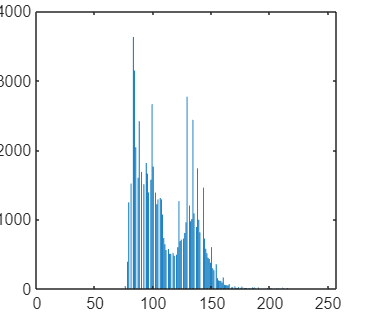

% p=imread('pout.tif');
% ret=myhist(p);
% bar(ret);

% function ret=myhist(I)
%     ret = zeros(256,1); % initialize histogram vector
%     [row, col]=size(I);
%     for i=1:row
%    
%         for j=1:col
%             ret(I(i,j)+1)=ret(I(i,j)+1)+1;
%         end
%     end
%     end 

ex4

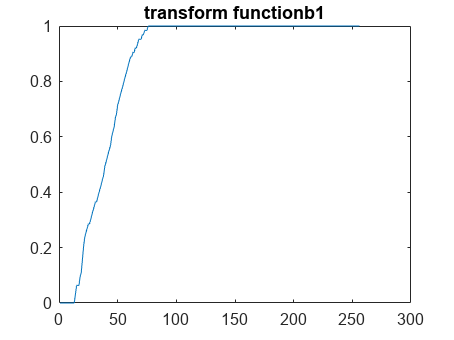

b1=imread('Fig3.15(a)1top.jpg');
[ph, t]=histeq(b1); % ph: equalized image, t: transformation 
plot(t), title('transform functionb1');

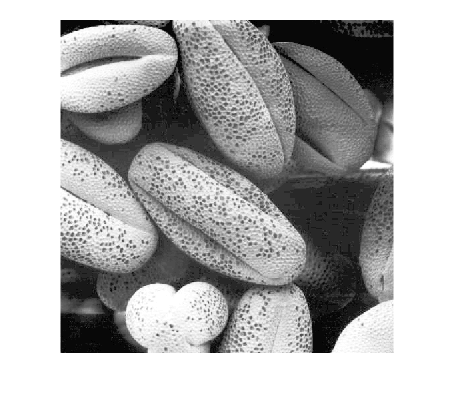

figure, imshow(ph)

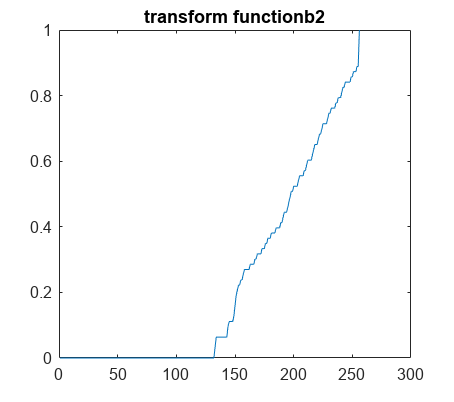

b2=imread('Fig3.15(a)2.jpg');
[ph2, t2]=histeq(b2); % ph: equalized image, t: transformation 
plot(t2), title('transform functionb2');

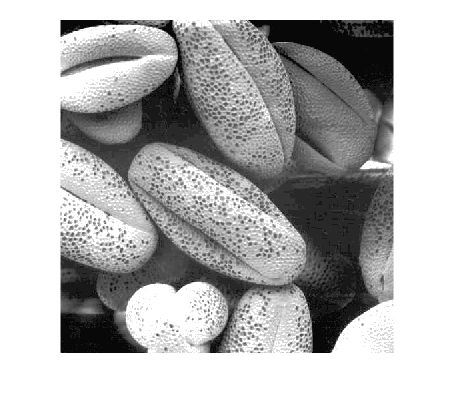

figure, imshow(ph2)

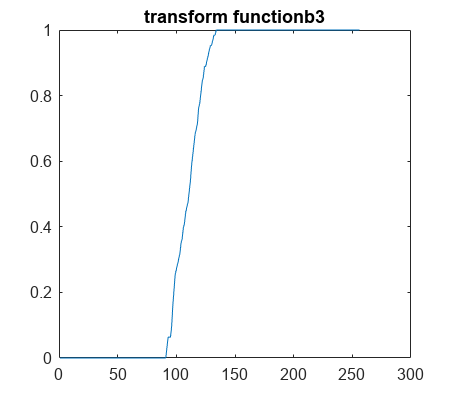

b3=imread('Fig3.15(a)3.jpg');
[ph3, t3]=histeq(b3); % ph: equalized image, t: transformation 
plot(t3), title('transform functionb3');

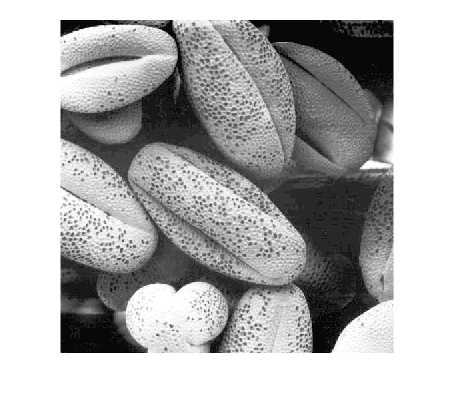

figure, imshow(ph3)